# GPINOUT

Demonstrates user interaction.

## Load data

load gPrices

## Choose a country (INPUTDLG)

myctry = inputdlg('Enter a country: ');
myctry = myctry{1};
idx = strcmp(myctry,country);

## Display information about country (FPRINTF)

Extract data for the chosen country.

myPrices = Prices(:,idx);

Display using FPRINTF and make a plot.

fprintf('Average gas price for %s is $%4.2f\n',myctry,mean(myPrices))

Average gas price for France is $4.41


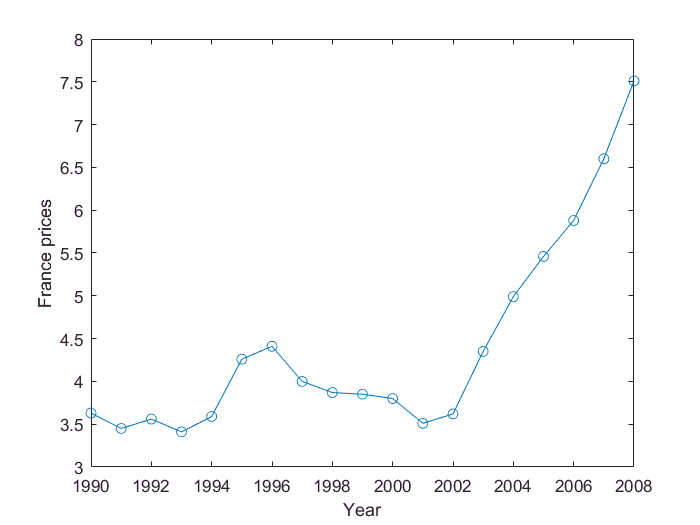

%  Make plot
plot(Year,myPrices,'o-')
xlabel('Year')
ylabel([myctry,' prices'])